
f = @(t,y) ((sin(2.*t) - 2.*t.*y)/(t.^2));

sol = @(t) ((-1.*cos(2.*t) + 4 + cos(2)) ./ (2.*t.^2) );
format long;
exact = sol(5);

exact = 0.0885

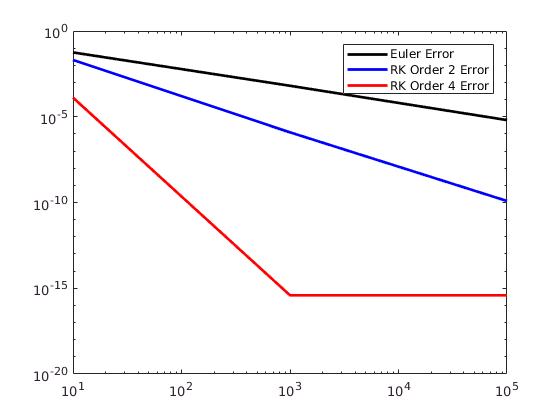



em_10 = euler_method(f,1,5,2,10);
rko2_10 = runge_kutta_order2(f,1,5,2,10);
rko4_10 = runge_kutta_order4(f,1,5,2,10);


em_10to3 = euler_method(f,1,5,2,10.^3);
rko2_10to3 = runge_kutta_order2(f,1,5,2,10.^3);
rko4_10to3 = runge_kutta_order4(f,1,5,2,10.^3);



em_10to5 = euler_method(f,1,5,2,10.^5);
rko2_10to5 = runge_kutta_order2(f,1,5,2,10.^5);
rko4_10to5 = runge_kutta_order4(f,1,5,2,10.^5);


em_result = [abs(em_10 - exact),abs(em_10to3-exact),abs(em_10to5-exact)];
rko2_result = [abs(rko2_10-exact),abs(rko2_10to3-exact),abs(rko2_10to5-exact)];
rko4_result = [abs(rko4_10-exact),abs(rko4_10to5-exact),abs(rko4_10to5-exact)];
n = [10,10.^3,10.^5];
loglog(n,em_result,'-k',n,rko2_result,'-b',n,rko4_result,'r','linewidth',2);
legend('Euler Error','RK Order 2 Error','RK Order 4 Error');
xlabel('n = [10,10^3,10^5]');
ylabel('Error');
title('Error plot');
hold off;

Obviously RK4 method produces the best approximization, and the euler's method is the worst. The reason why euler method 

is the worst, is because its error is being propagated trough the previous step, causing stacking effect where error is constantly increases. 

function w = euler_method(f,a,b,alpha,n)
    h = (b - a)/n;                        % calculate step
    x = a:h:b;                            % (t) points to evaluate at
    y = zeros(1,length(x));               % prepopulate y(length(x)) array
    y(1) = alpha;                         % set y(1) = alpha
    for i=1:(length(x)-1)                 % itarate from 11 to length(x) -1
        y(i + 1) = y(i) + h.*f(x(i),y(i));     % book equation for Euler
    end
    w = y(length(y));                     % get the last value
end
% also known as middle point
function w = runge_kutta_order2(f,a,b,alpha,n)
    h=(b - a) / n;                        % calculate setp                                                
    x = a:h:b;                            % (t) points to evaluate atZA
    y = zeros(1,length(x)); 
    y(1) = alpha;
    for i=1:(length(x)-1)
        % equation from the book
        k_1 = h*f(x(i),y(i));
        k_2 = h*f( (x(i) + h ./ 2), (y(i) + k_1 ./ 2));
        y(i+1) = y(i) + k_2;
    end
    % get the last value
    w = y(length(y));
end
function w = runge_kutta_order4(f,a,b,alpha,n)
    h=(b - a) / n;                                            
    x = a:h:b;                                        
    y = zeros(1,length(x)-1); 
    y(1) = alpha;      
    for i=1:(length(x)-1) 
        % equation from the book
        k_1 = f(x(i),y(i));
        k_2 = f(x(i)+0.5*h,y(i)+0.5*h*k_1);
        k_3 = f((x(i)+0.5*h),(y(i)+0.5*h*k_2));
        k_4 = f((x(i)+h),(y(i)+k_3*h));
        y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h; 
    end
    % get the last value
    w = y(length(y));
end